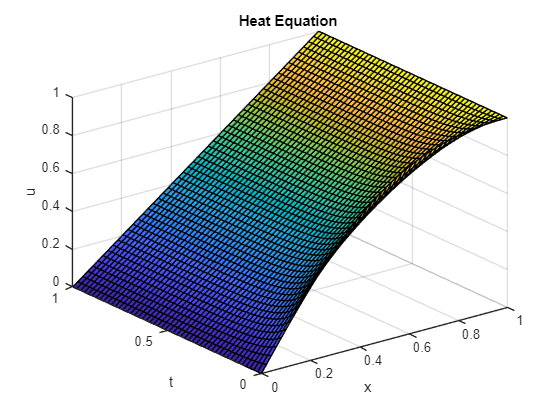

xm = linspace(0, 1, 50);  
timespan = linspace(0, 1, 50);   
m = 0; 
result = pdepe(m, @pdefunction, @initialcon, @boundrycon, xm, timespan);

function [c, f, s] = pdefunction(x, t, u, dudx) 
    c = 1;
    f = dudx;
    s = 0;
end

function [pl, ql, pr, qr] = boundrycon(xl, ul, xr, ur, t)
    pl = ul;  
    ql = 0;
    pr = ur-1;  
    qr = 0;
end
function u0 = initialcon(x)
    u0 = (2*x) / (x^2 + 1);  
end



u = result(:,:,:);
surf(xm, timespan, u);
xlabel('x');
ylabel('t');
zlabel('u');
title('Heat Equation ');

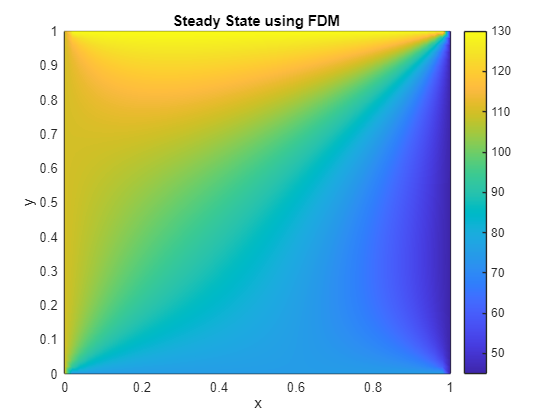


nx = 50;
ny = 50;
W = 1;
H = 1;

dx = W / (nx - 1);
dy = H / (ny - 1);


T = 25 * ones(ny, nx);

T(1, :) = 75;
T(end, :) = 130;
T(:, 1) = 110;
T(:, end) = 45;


maxiter = 5000; 
tol = 1e-5;

for iter = 1:maxiter
    T_old = T;
    
    for i = 2:ny-1
        for j = 2:nx-1
            
           T(i, j) = 0.5 * (1 / (dx^2 + dy^2)) * (dy^2 * (T(i+1, j) + T(i-1, j)) + dx^2 * (T(i, j+1) + T(i, j-1)));

        end
    end
     
    if max(abs(T(:) - T_old(:))) < tol
        break;
    end
end


x = linspace(0, W, nx);
y = linspace(0, H, ny);
pcolor(x, y, T);
shading interp;
colorbar;
title('Steady State using FDM ');
xlabel('x');
ylabel('y');

At least one END is missing. The statement beginning here does not have a matching end.

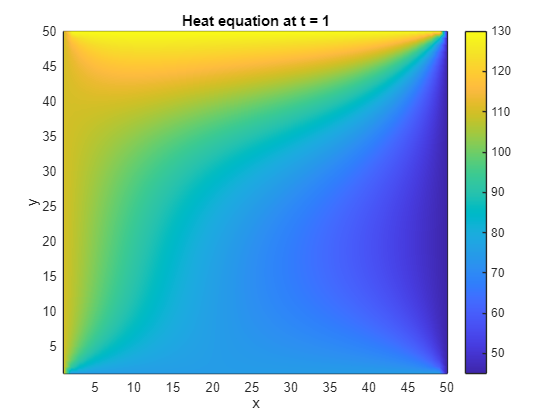

dt = 0.001; 
t_end = 1;
alpha = 0.1; 

T = 25 * ones(ny, nx); 

T(1, :) = 75;   
T(end, :) = 130; 
T(:, 1) = 110;   
T(:, end) = 45;  

for t = 0:dt:t_end
    T_old = T;
    
    for i = 2:ny-1
        for j = 2:nx-1
            T(i, j) = T_old(i, j) + alpha * dt * ((T_old(i+1, j) - 2*T_old(i, j) + T_old(i-1, j)) / dx^2 + (T_old(i, j+1) - 2*T_old(i, j) + T_old(i, j-1)) / dy^2 );
        end
    end
    
    
    if mod(t, 0.01) == 0
        pcolor(T);
        shading interp;
        colorbar;
        title(['Heat equation at t = ', num2str(t)]);
        xlabel('x');
        ylabel('y');
        drawnow;
    end
% end